%% 冰Ih基面伊辛模型 - 多条MC轨迹的系综分析
%  同时跑N_runs条MC，画出：
%  1. 所有轨迹（灰色细线）
%  2. 系综均值（蓝色粗线）
%  3. 均值±标准差（蓝色阴影区域）

clear; clc; close all;

%% ══ 参数 ════════════════════════════════════════════
Lx = 8;
Ly = 6;
N     = Lx * Ly;
N_occ = N / 2;

epsilon_meV  = 76.0;
kB_meV_per_K = 0.08617;

%% ══ 构建近邻列表 ════════════════════════════════════
nn_dix = [+1, -1,  0,  0, +1, -1];
nn_diy = [ 0,  0, +1, -1, -1, +1];

nn_list = zeros(N, 6, 'int32');
for iy = 1:Ly
    for ix = 1:Lx
        idx = (iy-1)*Lx + ix;
        for k = 1:6
            nx = mod(ix - 1 + nn_dix(k), Lx) + 1;
            ny = mod(iy - 1 + nn_diy(k), Ly) + 1;
            nn_list(idx, k) = int32((ny-1)*Lx + nx);
        end
    end
end

%% ══ 设置 ════════════════════════════════════════════
%
%  ★ 可以改的地方：
%    init_mode : 'random' 或 'stripe'
%    T         : 温度（建议先试300，再试10）
%    N_runs    : 跑几条轨迹（建议10~30条）
%    N_steps   : 每条跑多少步
%    measure   : 每隔多少步记录一次
%
init_mode = 'random';   % ← 初始条件
T         = 300;        % ← 温度 (K)
N_runs    = 1000;         % ← 轨迹条数
N_steps   = 600;      % ← 每条轨迹的步数
measure   = 1;         % ← 记录间隔

beta = 1.0 / (kB_meV_per_K * T);

n_meas   = floor(N_steps / measure) + 1;  % 每条轨迹的记录点数
steps_ax = [0, (1:n_meas-1) * measure];   % 横轴（步数）

% 存所有轨迹
COH_all = zeros(N_runs, n_meas);

fprintf('T = %d K，初始条件：%s，跑 %d 条轨迹...\n', T, init_mode, N_runs);

T = 300 K，初始条件：random，跑 1000 条轨迹...



%% ══ 主循环：跑N_runs条独立轨迹 ═════════════════════
for run = 1:N_runs

    % 每条轨迹独立初始化
    if strcmp(init_mode, 'stripe')
        occ = false(N, 1);
        for iy = 1:Ly
            if mod(iy, 2) == 1
                for ix = 1:Lx
                    occ((iy-1)*Lx + ix) = true;
                end
            end
        end
    elseif strcmp(init_mode, 'random')
        occ = false(N, 1);
        occ(randperm(N, N_occ)) = true;
    end

    occ_idx  = int32(find(occ));
    free_idx = int32(find(~occ));

    % 第0步：记录初始值
    cnt = 1;
    COH_all(run, cnt) = calc_COH(occ, nn_list, N_occ);

    % MC主循环
    for step = 1:N_steps
        [occ, occ_idx, free_idx] = mc_swap( ...
            occ, occ_idx, free_idx, nn_list, N_occ, beta, epsilon_meV);

        if mod(step, measure) == 0
            cnt = cnt + 1;
            COH_all(run, cnt) = calc_COH(occ, nn_list, N_occ);
        end
    end

    %fprintf('  轨迹 %2d 完成，最终C_OH = %.4f\n', run, COH_all(run, end));
end

%% ══ 统计 ════════════════════════════════════════════
COH_mean_t = mean(COH_all, 1);   % 每个时间点的均值（沿runs方向）
COH_std_t  = std(COH_all,  0, 1);% 每个时间点的标准差

% 最终平衡值（用最后20个点）
equil_start   = max(1, n_meas - 20);
COH_equil     = mean(COH_mean_t(equil_start:end));
COH_equil_std = mean(COH_std_t(equil_start:end));

fprintf('\n平衡态均值  = %.4f\n', COH_equil);


平衡态均值  = 2.1317


fprintf('平衡态标准差 = %.4f\n', COH_equil_std);

平衡态标准差 = 0.0909


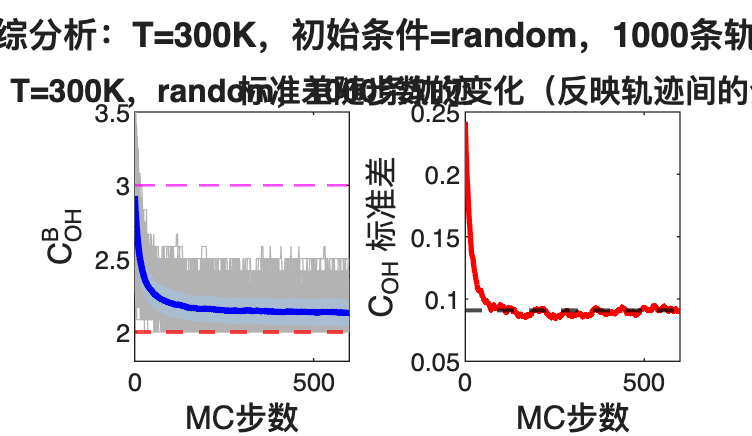


%% ══ 画图 ════════════════════════════════════════════
figure('Color', 'white', 'Position', [100, 100, 950, 550]);

%% 子图1：所有轨迹 + 均值 + 标准差
subplot(1, 2, 1);

% 先画所有轨迹（灰色细线）
for run = 1:N_runs
    plot(steps_ax, COH_all(run, :), '-', ...
        'Color', [0.7 0.7 0.7], 'LineWidth', 0.5); hold on;
end

% 画均值±std的阴影区域
fill([steps_ax, fliplr(steps_ax)], ...
     [COH_mean_t + COH_std_t, fliplr(COH_mean_t - COH_std_t)], ...
     [0.6 0.8 1.0], 'FaceAlpha', 0.4, 'EdgeColor', 'none', ...
     'DisplayName', '均值±标准差');

% 画均值曲线（蓝色粗线）
plot(steps_ax, COH_mean_t, 'b-', 'LineWidth', 2.5, ...
    'DisplayName', '系综均值');

% 参考线
yline(2.0, 'r--', 'LineWidth', 1.5, 'DisplayName', 'C_{OH}=2.0（基态）');
yline(3.0, 'm--', 'LineWidth', 1.0, 'DisplayName', 'C_{OH}≈3.0（随机）');

xlabel('MC步数',    'FontSize', 12);
ylabel('C_{OH}^B', 'FontSize', 12);
title(sprintf('T=%dK，%s，%d条轨迹', T, init_mode, N_runs), ...
    'FontSize', 12, 'FontWeight', 'bold');
%legend('FontSize', 9, 'Location', 'best');
ylim([1.8, 3.5]);
grid off; box on;

%% 子图2：标准差随步数的变化
subplot(1, 2, 2);

plot(steps_ax, COH_std_t, 'r-', 'LineWidth', 2.0); hold on;
yline(COH_equil_std, 'k--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('平衡标准差=%.4f', COH_equil_std));

xlabel('MC步数',            'FontSize', 12);
ylabel('C_{OH} 标准差',     'FontSize', 12);
title('标准差随步数的变化（反映轨迹间的分散程度）', ...
    'FontSize', 12, 'FontWeight', 'bold');
%legend('FontSize', 10, 'Location', 'best');
grid off; box on;

sgtitle(sprintf('系综分析：T=%dK，初始条件=%s，%d条轨迹', ...
    T, init_mode, N_runs), 'FontSize', 13, 'FontWeight', 'bold');


%% ══════════════════════════════════════════════════════
%%  本地函数
%% ══════════════════════════════════════════════════════

function [occ, occ_idx, free_idx] = mc_swap( ...
        occ, occ_idx, free_idx, nn_list, N_occ, beta, epsilon)
    i_pos = randi(N_occ);
    j_pos = randi(N_occ);
    i = occ_idx(i_pos);
    j = free_idx(j_pos);

    c_i = sum(occ(nn_list(i, :)));
    c_j = sum(occ(nn_list(j, :)));

    if any(nn_list(i, :) == j)
        delta_E = epsilon * double(c_j - 1 - c_i);
    else
        delta_E = epsilon * double(c_j - c_i);
    end

    if delta_E <= 0 || rand() < exp(-beta * delta_E)
        occ(i)          = false;
        occ(j)          = true;
        occ_idx(i_pos)  = j;
        free_idx(j_pos) = i;
    end
end

function COH = calc_COH(occ, nn_list, N_occ)
    occ_rows      = nn_list(occ, :);
    nn_occ_matrix = occ(occ_rows);
    COH = double(sum(nn_occ_matrix(:))) / N_occ;
end